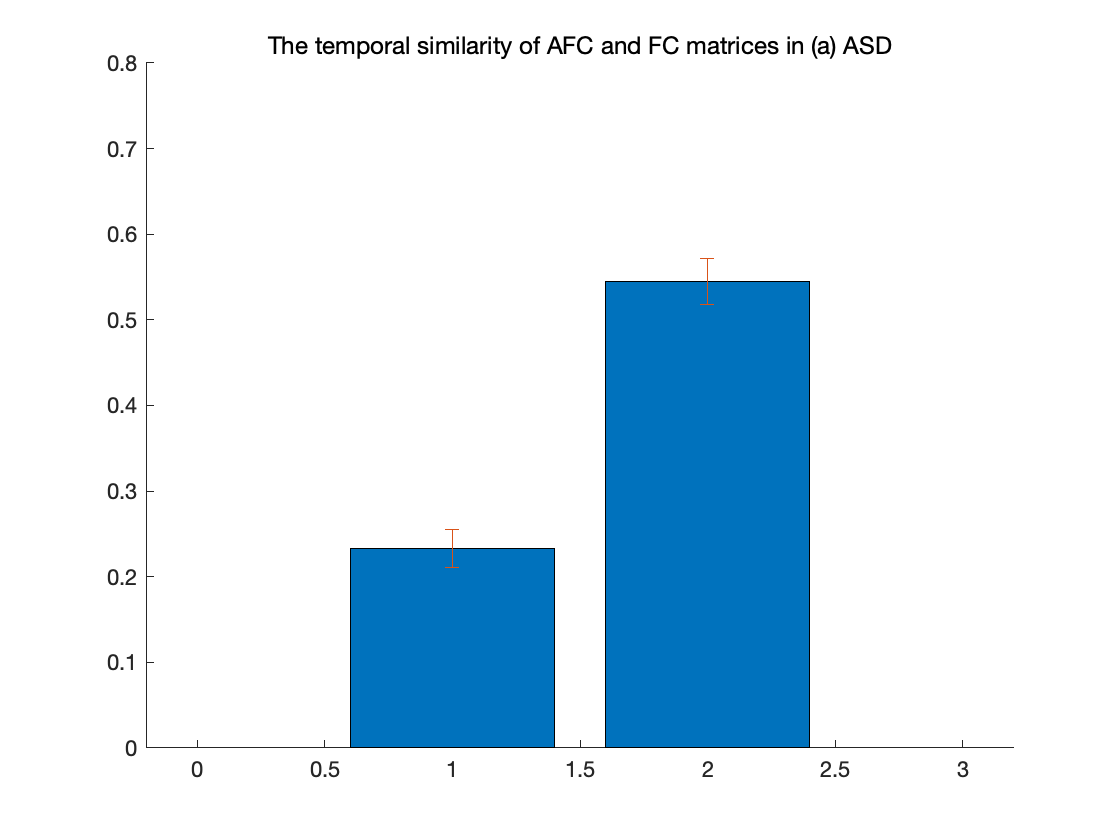

clear
clc
warning off

load sub_network_label.mat
label_NC = 56:110; % healthy control

load mean_p.mat


% plot temporal similarity
figure
hold on
bar(mean(p(label_NC, :)))
errorbar(mean(p(label_NC, :)), std(p(label_NC, :)), 'LineStyle', 'none')
ylim([0 0.8])
title('The temporal similarity of AFC and FC matrices in (a) ASD')


[H,P,CI,STATS] = ttest2(p(label_NC, 1), p(label_NC, 2))

H = single
1

P = single
0

CI = 2×1 single 列向量
   -0.3206
   -0.3020


STATS = 包含以下字段的 struct :
    tstat: -66.1062
       df: 108
       sd: 0.0247


clear
clc

label_NC = 56:110;

load Data_graph.mat

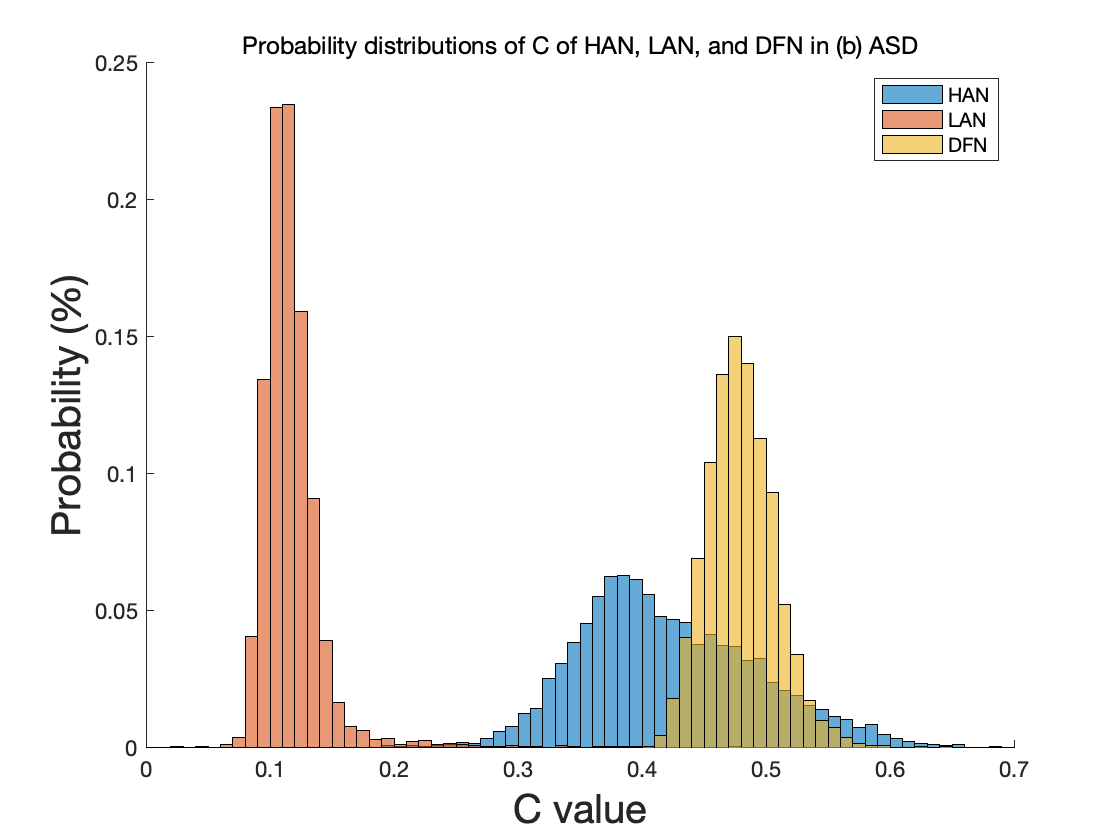

% plot C

data_NC = C(label_NC, :, :);
data_NC_mean = squeeze(mean(C(label_NC, :, :), 2));
data_NC_std = squeeze(std(C(label_NC, :, :), [], 2));
data_NC = reshape(data_NC, [55*91, 3]);


% plot distribution
figure
hold on

for i = 1:3
data = data_NC(:, i);
data = data(:);

binWidth = 0.01;
lastVal = 0.7;
binEdges = 0:binWidth:lastVal;
h = histogram(data,binEdges, 'Normalization', "probability");
xlabel('C value', "FontSize", 20);
ylabel('Probability (%)', "FontSize", 20);
xlim([0 0.7])
end
title('Probability distributions of C of HAN, LAN, and DFN in (b) ASD')
legend({'HAN', 'LAN', 'DFN'})

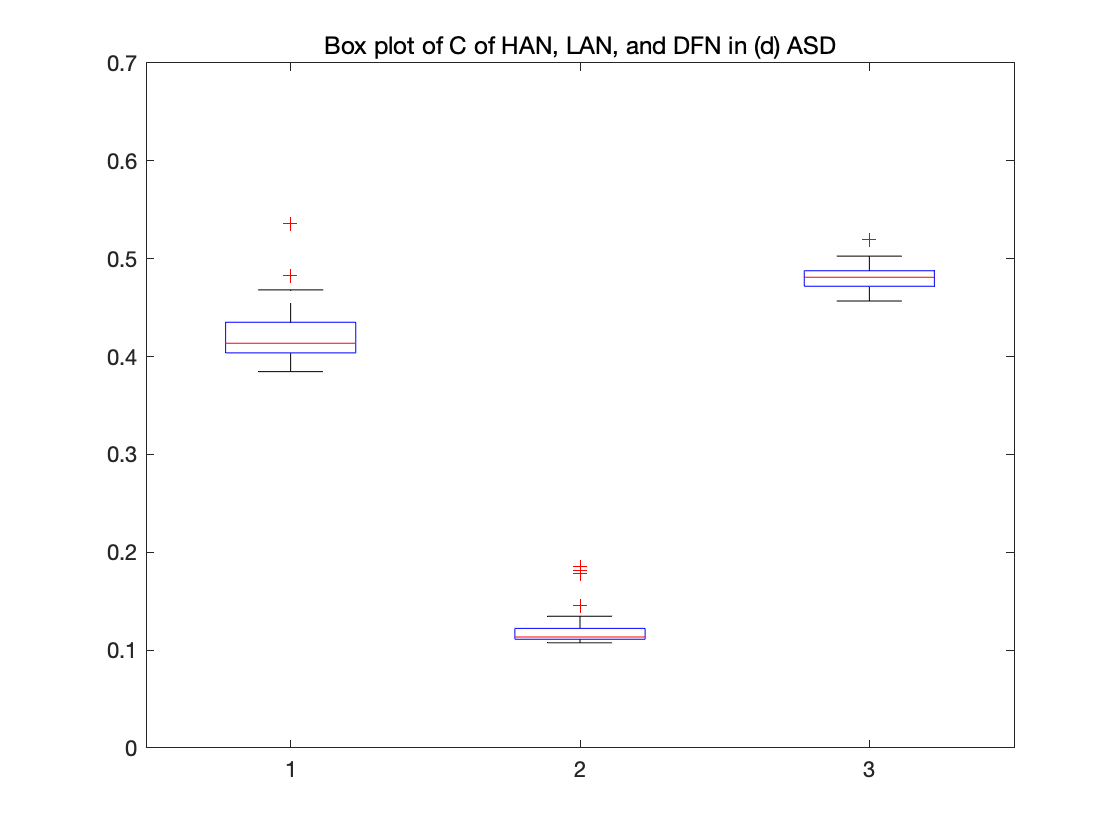



% box plot
figure
boxplot(data_NC_mean)
ylim([0 0.7])
title('Box plot of C of HAN, LAN, and DFN in (d) ASD')


[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 2));
p(1) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 3));
p(2) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 2), data_NC_mean(:, 3));
p(3) = P;

% fdr correct HAN, LAN, DFN
p = mafdr(p, 'BHFDR', true)

p = 	1.0e+-27 *

    0.0000    0.4815    0.0000


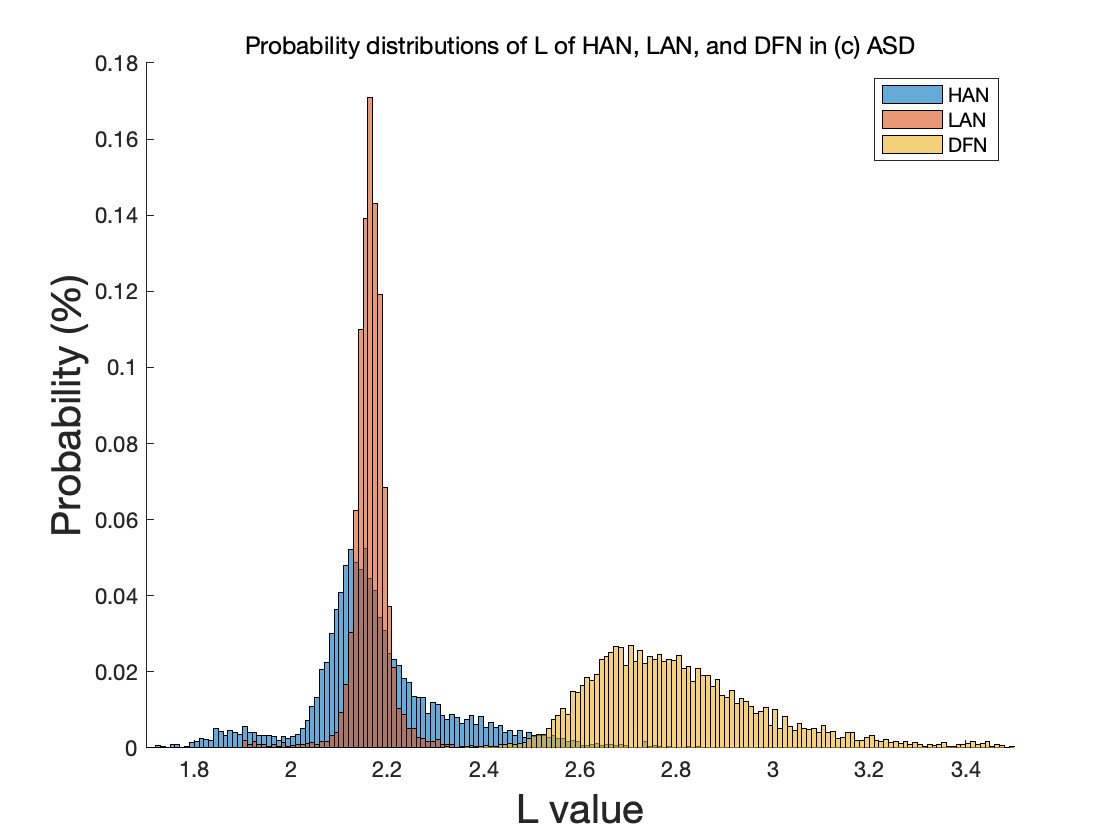

% plot L

data_NC = L(label_NC, :, :);
data_NC_mean = squeeze(mean(L(label_NC, :, :), 2));
data_NC_std = squeeze(std(L(label_NC, :, :), [], 2));
data_NC = reshape(data_NC, [55*91, 3]);


% plot distribution
figure
hold on

for i = 1:3
data = data_NC(:, i);
data = data(:);

binWidth = 0.01;
lastVal = 3.5;
binEdges = 1.5:binWidth:lastVal;
h = histogram(data,binEdges, 'Normalization', "probability");
xlabel('L value', "FontSize", 20);
ylabel('Probability (%)', "FontSize", 20);
xlim([1.7 3.5])
end
title('Probability distributions of L of HAN, LAN, and DFN in (c) ASD')
legend({'HAN', 'LAN', 'DFN'})

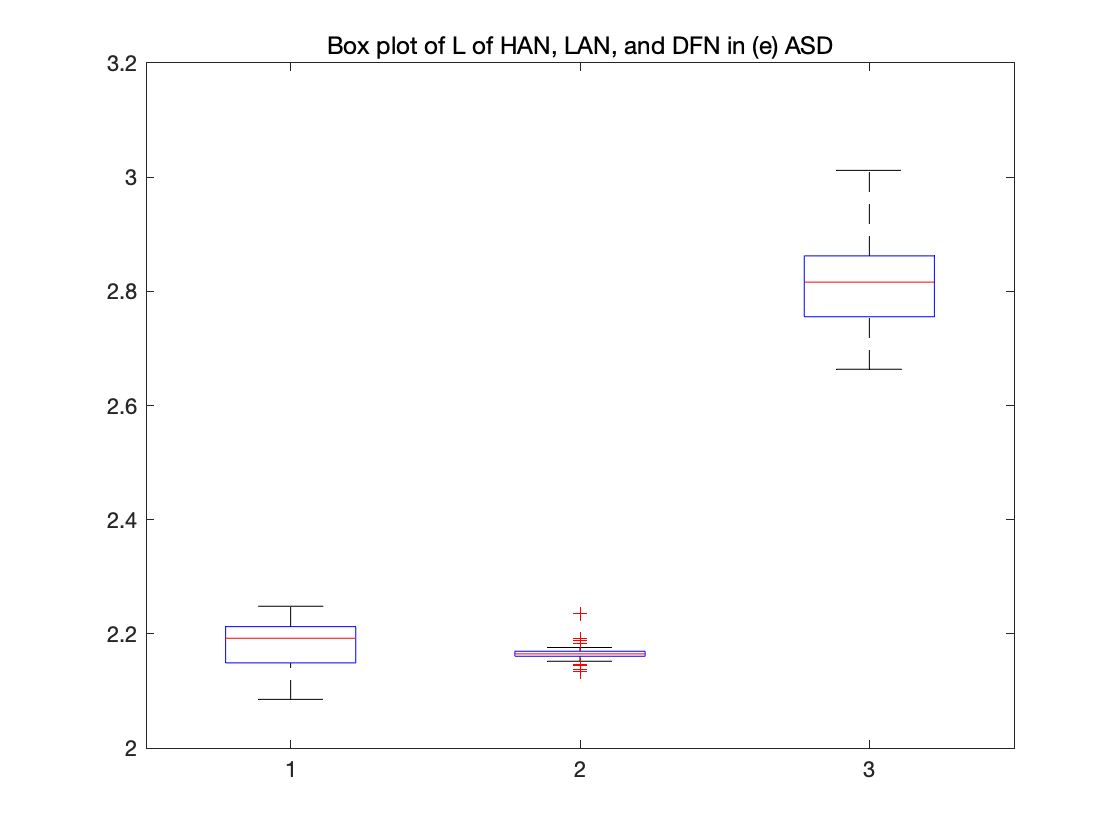



% box plot
figure
boxplot(data_NC_mean)
ylim([2 3.2])
title('Box plot of L of HAN, LAN, and DFN in (e) ASD')


[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 2));
p(1) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 3));
p(2) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 2), data_NC_mean(:, 3));
p(3) = P;

% fdr correct HAN, LAN, DFN
p = mafdr(p, 'BHFDR', true)

p =     0.0110    0.0000    0.0000
